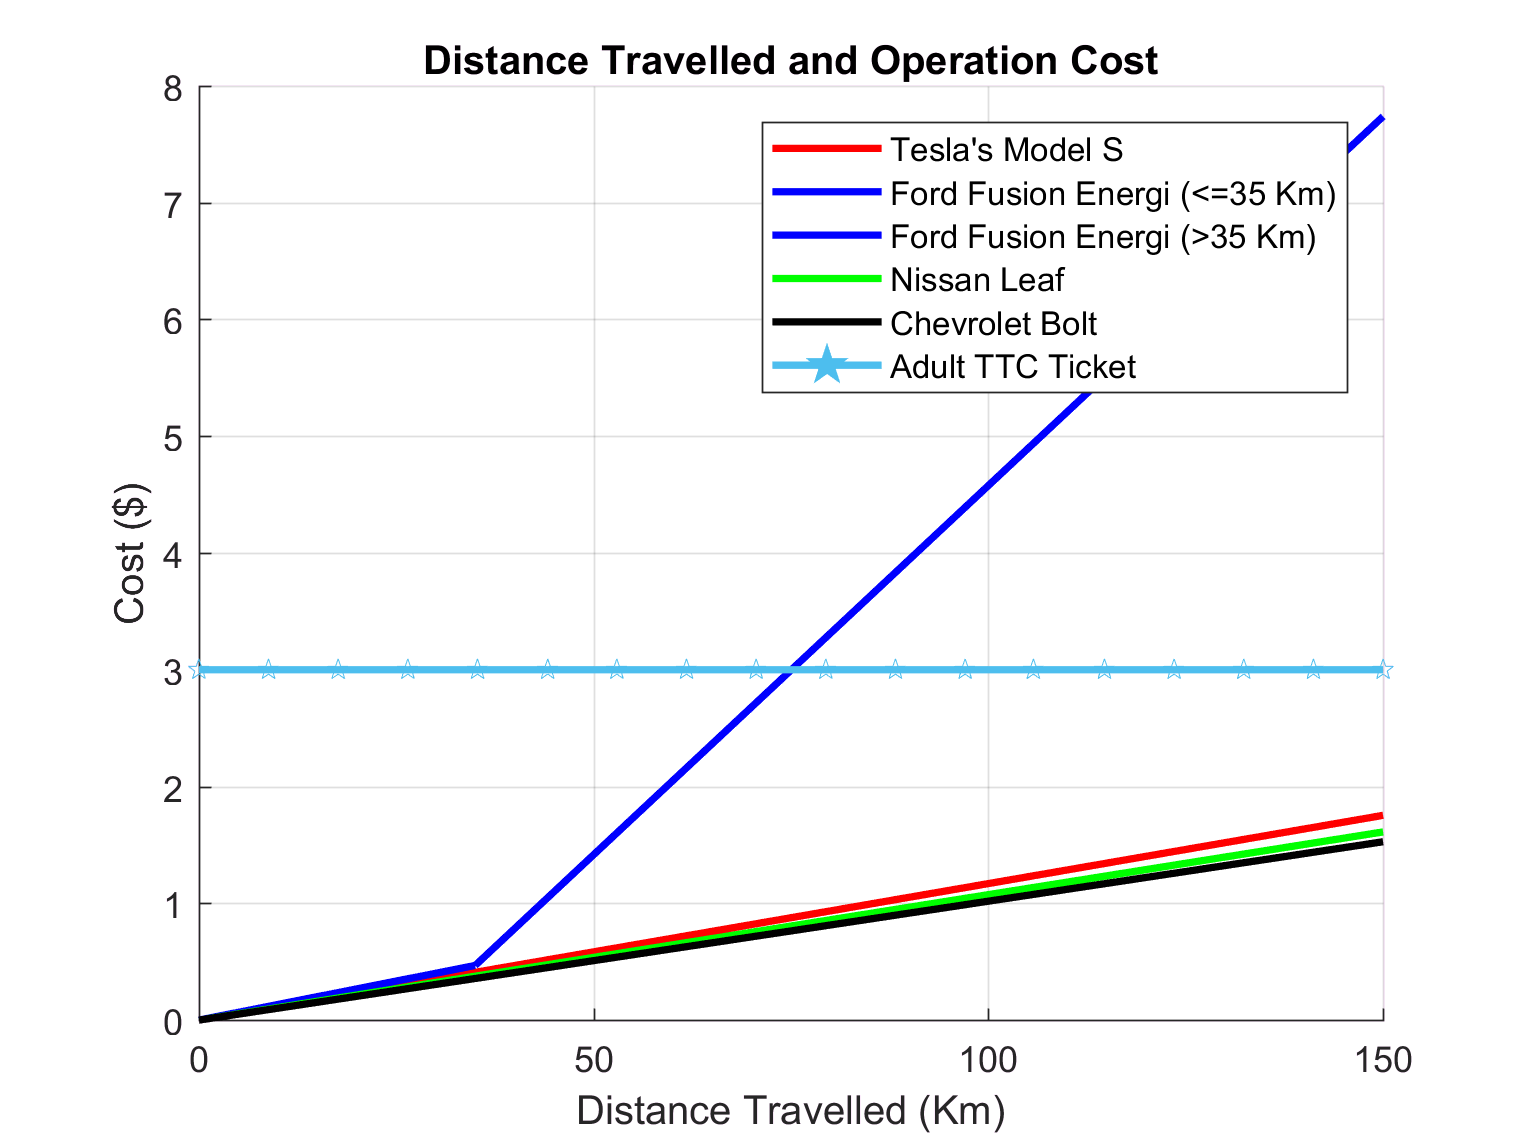

% Close and Clear Everything
close all; clear all;

% A. GIVEN INFORMATION / SET VARIABLES
standard_fuel_economy = 9.0;    %[L/100Km]

%Info for Vehicles
    %base price [$CAD] (1) | government credit [$CAD] (2) | manufacturer rebate [$CAD] (3) | total cost [$CAD] (4) |
    %battery capacity [kWh] (5) | estimated battery range [Km] (6) | recharge time [h] (7) | fuel consumption [L/100 Km] (8) |
vehicle_data = [96650, 14000, 0, NaN, 75, 417, 12, NaN;     %Tesla's Model S
                33588, 7000, 1500, NaN, 7.2, 35, 2.5, 5.6;    %Ford Fusion Energi
                35998, 14000, 0, NaN, 40, 242, 8, NaN;      %Nissan Leaf
                43095, 14000, 0, NaN, 60, 383, 9.3, NaN];   %Chevrolet Bolt
ford_range = 35;    %[km]
            
%Cost
fuel_cost = 1.129;           %$/liter
electricity_cost = 0.065;    %$/KWh

%Cost of Operation for Each of the Four Vehicles
    %m = distances of 11 destinations
    %n = 4 vehicles: electricity cost [$/Km] (1) | gasoline cost [$/Km] (2) | total cost [$/Km] (3) |
cost_per_km = NaN(2,4);
cost_per_trip = NaN(11,4);

%Shortest Distance from Selected Locations to Bahen Center Garage [Km]
distance = [1.7;     %(1) Eaton Center: 220 Yonge St, Toronto, ON M5B 2H1
            8.0;     %(2) Sky Zone Trampoline Park: 45 Esandar Dr, Unit 1A, Unit 1A, Toronto, ON M4G 4C5
            10.7;    %(3) Lambton Golf & Country Club: 100 Scarlett Rd, York, ON M6N 4K2
            19.2;    %(4) Bluffer's Park Beach: 1 Brimley Road S, Scarborough, ON M1M 3W3
            25.1;    %(5) Toronto Pearson International Airport: 6301 Silver Dart Dr, Mississauga, ON L5P 1B2
            28.4;    %(6) Highcastle Public School: 370 Military Trail, Scarborough, ON M1E 4E6
            30.9;    %(7) Canada's Wonderland: 1 Canada's Wonderland Drive, Vaughan, ON L6A 1S6
            39.6;    %(8) Pickering Nuclear Generating Station Information Centre: 675 Sandy Beach Rd, Pickering, ON L1W 3X5
            45.3;    %(9) Pine Farms Orchard: 2700 16th Sideroad, King City, ON L7B 1A3
            49.3;    %(10) Casino Ajax: 50 Alexander's Crossing, Ajax, ON L1Z 2E6
            130];    %(11) Niagara Falls, ON



% B. CALCULATIONS
%Final Cost of Each Vehicle
vehicle_data(:,4) = vehicle_data(:,1) - (vehicle_data(:,2)+vehicle_data(:,3));

%Cost Per Kilometer
cost_per_km(1,:) = (vehicle_data(:,5)*electricity_cost) ./ (vehicle_data(:,6));    %electricity
cost_per_km(2,2) = (fuel_cost * vehicle_data(2,8)) / 100;    %gasoline for Ford Fusion Energi

%Convert Cost Per Kilometer to Function
syms d;                                                    %d = distance travelled
tesla = cost_per_km(1,1)*d;
ford_L = cost_per_km(1,2)*d;                               %<=35 Km
ford_G = cost_per_km(2,2)*(d-35) + cost_per_km(1,2)*35;    %>35 Km
nissan = cost_per_km(1,3)*d;
chevrolet = cost_per_km(1,4)*d;
TTC = 3.00;                                                %TTC adult fare cost [$CAD]

%Cost Per Trip
for i = 1:4
    cost_per_trip(:,i) = cost_per_km(1,i) .* distance;
end
for i = 1:11
    if distance(i) > 35
        cost_per_trip(i,2) = cost_per_km(2,2)*(distance(i)-ford_range) + cost_per_km(1,2)*ford_range;    %use gasoline for ford when >35 Km
    end
end

%Distance Required to Pay Back the Cost of Vehicle Using Money Saved
standard_cost_per_km = (fuel_cost * standard_fuel_economy) / 100;
tesla_saved = (standard_cost_per_km*d) - tesla;
ford_saved = (standard_cost_per_km*d) - ford_G;
nissan_saved = (standard_cost_per_km*d) - nissan;
chevrolet_saved = (standard_cost_per_km*d) - chevrolet;

% C. Plotting Graphs
%Plot 1: Relationship Between Distance Travelled And Operating Cost
hold on;
grid on;
fplot(tesla,'-r','LineWidth',2);
fplot(ford_L,'-b',[0,35],'LineWidth',2);
fplot(ford_G,'-b',[35,150],'LineWidth',2);
fplot(nissan,'-g','LineWidth',2);
fplot(chevrolet,'-black','LineWidth',2);
fplot(TTC,'-p','LineWidth',2);
xlim([0, 150]);
ylim([0, 8]);
title('Distance Travelled and Operating Cost');
xlabel('Distance Travelled (Km)');
ylabel('Cost ($)');
legend("Tesla's Model S",'Ford Fusion Energi (<=35 Km)','Ford Fusion Energi (>35 Km)','Nissan Leaf','Chevrolet Bolt','Adult TTC Ticket');
hold off;

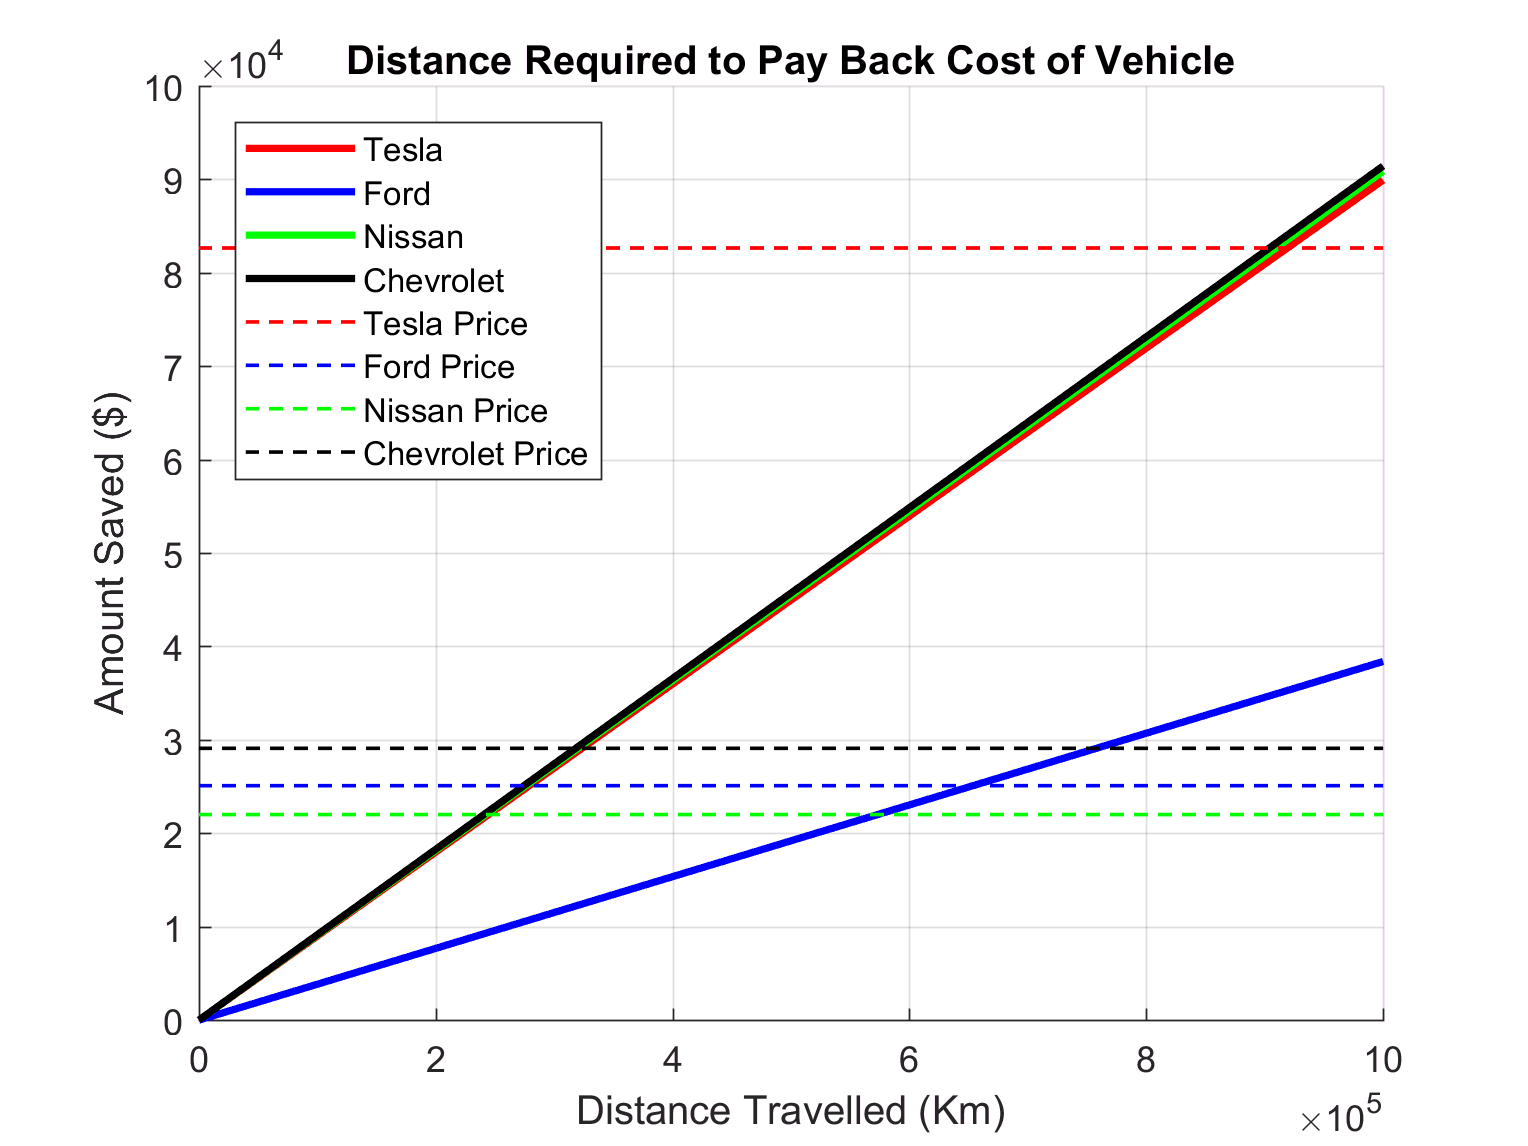


%Plot 2: Distance Required to Pay Back Cost of Vehicle
figure;
hold on;
grid on;
fplot(tesla_saved,'-r','LineWidth',2);
fplot(ford_saved,[35,1E6],'-b','LineWidth',2);
fplot(nissan_saved,'-g','LineWidth',2);
fplot(chevrolet_saved,'-black','LineWidth',2);
fplot(vehicle_data(1,4),'--r','LineWidth',1);
fplot(vehicle_data(2,4),[35,1E6],'--b','LineWidth',1);
fplot(vehicle_data(3,4),'--g','LineWidth',1);
fplot(vehicle_data(4,4),'--black','LineWidth',1);
xlim([0, 1E6]);
ylim([0, 1E5]);
title('Distance Required to Pay Back Cost of Vehicle');
xlabel('Distance Travelled (Km)');
ylabel('Amount Saved ($)');
legend({'Tesla','Ford','Nissan','Chevrolet','Tesla Price','Ford Price','Nissan Price','Chevrolet Price'},'Location','northwest');
hold off;




% D. ANSWERS
%Question 1: Which vehicle, from those listed, is the most economical overall? Why?
    %From Plot 1, Chevrolet Bolt is the most economical due to its low operating cost. However, from Plot 2, the Nissan Leaf comes out with
    %the fastest to pay back the cost of the vehicle using the money saved when compared to the standard fuel economy of 9L/100Km. As a
    %result, in the long run, the Chevrolet Bolt will be the most economical, but in the short term with fewer distance driven, then the
    %Nissan Leaf is better.
%Question 2: Which vehicle, from those listed, is most economical at each 10km radius away from Toronto? What impact, if any, does average
%traffic have on this?
    %From Plot 1, it seems that the Chevrolet Bolt ranks consistently to be the most economical at each of 10 Km radius away from Toronto.
    %Since all vehicles are either pure electric or hybrids, average traffic does not play a significant role in affecting the fuel and
    %power consumption because unlike regular gasoline engines, electric and hybrid engines do not idle and instead, they turn off
    %automatically when not in use.
%Question 3: How does this compare to existing transit infrastructure (or walking or biking)? What are other concerns to take into
%consideration?
    %From Plot 1, the $3.00 CAD adult TTC fare was included to illustrate the necessary distance travelled by each vehicle per trip to
    %equate to one fare cost. Usually, TTC rides span a max of tens of kilometers in distance since any longer than that would mean more
    %than several hours of commute time. As a result, all four vehicles prove to be great candidates over existing transit infrastructure
    %such as the TTC. Nevertheless, when travelling short distances such as under 5 Km, for example, other, more eco-friendly solutions
    %such as walking or biking may be preferred over driving. Concerns such as parking availability, parking fees, and traffic congestion
    %are some of the key factors that may inhibit one from choosing to drive over methods such as taking the TTC, walking, and or biking.
%Question 4: A brief description of ways in which you had to adapt your plan from that which you originally envisioned in Step 2 above.
    %My initial plan from Step 2 did not consider the fare cost of the TTC nor the assumed standard average fuel economy. The inclusion
    %of the TTC fare enhances the comparison of whether to choose to drive each of the four vehicles over other transportation methods
    %such as using the TTC. The inclusion of the assumed standard average fuel economy allowed me to create the second plot which also
    %aids in determining which vehicle is the most economical in terms of their price.
%Conclusion Statement
    %The Chevrolet Bolt and the Nissan Leaf are the two most economical vehicles out of the four. If one plans to use the vehicle for a
    %long time and drives long distances, then the Chevrolet Bolt is the top choice in terms of being the most economical. If not, then
    %the Nissan Leaf would be the top choice.